# MATLABエージェントによるAlgorithm3の実装

## 環境の宣言

A = [-1 2; 2.2 1.7];
B = [2; 1.6];
C = [1 2];
F = -1;

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];

x0 = [5; -5; 5];

### 報酬関数の設計

Q = 6;
R = 1;

Q1 = C1'*Q*C1;

### 環境のインスタンス

env = myDiscreteEnv(T,B1,Q1,R);
env = DiscreteLQTEnv(A,B,C,F,Q,R, x0);
% rng(0)

## エージェントの作成

% K0 = place(A,B,[0.4,0.8,0.5]);
K0 = [0.3 1.3 0.75];
agent = LQTAgent(Q1,R,K0);

## エージェントの学習

trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',10, ...
    'MaxStepsPerEpisode',100, ...
    'Verbose',true, ...
    'Plots','none');

trainingStats = train(agent,env,trainingOpts);

Episode:   1/ 10 | Episode Reward : -12104478720.00 | Episode Steps:  100 | Avg Reward : -12104478720.00 | Step Count : 100
Episode:   2/ 10 | Episode Reward : -359595.00 | Episode Steps:  100 | Avg Reward : -6052419072.00 | Step Count : 200
Episode:   3/ 10 | Episode Reward : -346884.28 | Episode Steps:  100 | Avg Reward : -4035061760.00 | Step Count : 300
Episode:   4/ 10 | Episode Reward : -291873.66 | Episode Steps:  100 | Avg Reward : -3026369280.00 | Step Count : 400
Episode:   5/ 10 | Episode Reward : -387399.28 | Episode Steps:  100 | Avg Reward : -2421172736.00 | Step Count : 500
Episode:   6/ 10 | Episode Reward : -396369.28 | Episode Steps:  100 | Avg Reward : -356424.28 | Step Count : 600
Episode:   7/ 10 | Episode Reward : -278686.38 | Episode Steps:  100 | Avg Reward : -340242.56 | Step Count : 700
Episode:   8/ 10 | Episode Reward : -343194.94 | Episode Steps:  100 | Avg Reward : -339504.69 | Step Count : 800
Episode:   9/ 10 | Episode Reward : -471398.66 | Episode Steps

## シミュレーション結果の検証

simOptions = rlSimulationOptions('MaxSteps', 100);
experience = sim(env,agent,simOptions);
totalReward = sum(experience.Reward)

totalReward = single
-8.5018e+03

% [Koptimal,P] = dlqr(T,B1,Q1,R);
gamma = agent.Gamma;

A = sqrt(gamma)*T;
B = sqrt(gamma)*B1;
S = 0;
Q = Q1;
R = R;
[P, Koptimal, ~] = idare(A, B, Q, R, [], []);

% x0 = experience.Observation.obs1.getdatasamples(1);
% Joptimal = -x0'*P*x0;
% rewardError = totalReward - Joptimal

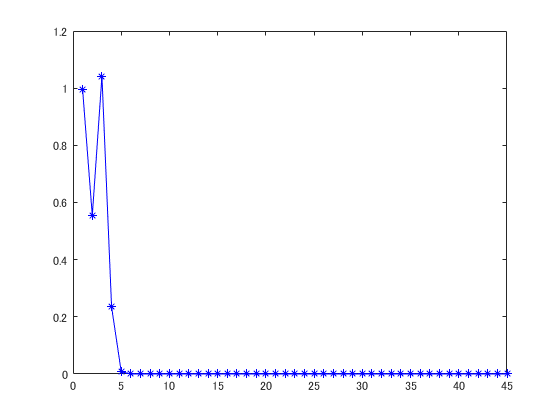

% number of gain updates
len = agent.KUpdate;
err = zeros(len,1);
for i = 1:len
    % norm of error in the gain
    err(i) = norm(agent.KBuffer{i}-Koptimal);
end  
plot(err,'b*-')

gainError = norm(agent.K - Koptimal)

gainError = single
8.6644e-07

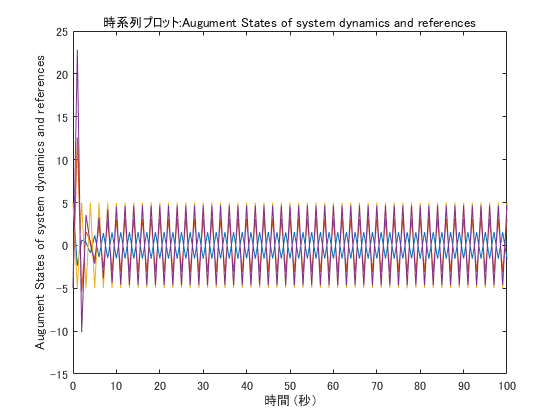

obs = experience.Observation.AugumentStatesOfSystemDynamicsAndReferences;
plot(obs);
X = squeeze(obs.Data);
y = C * X(1:2, :);
hold on;
plot(obs.Time, y);